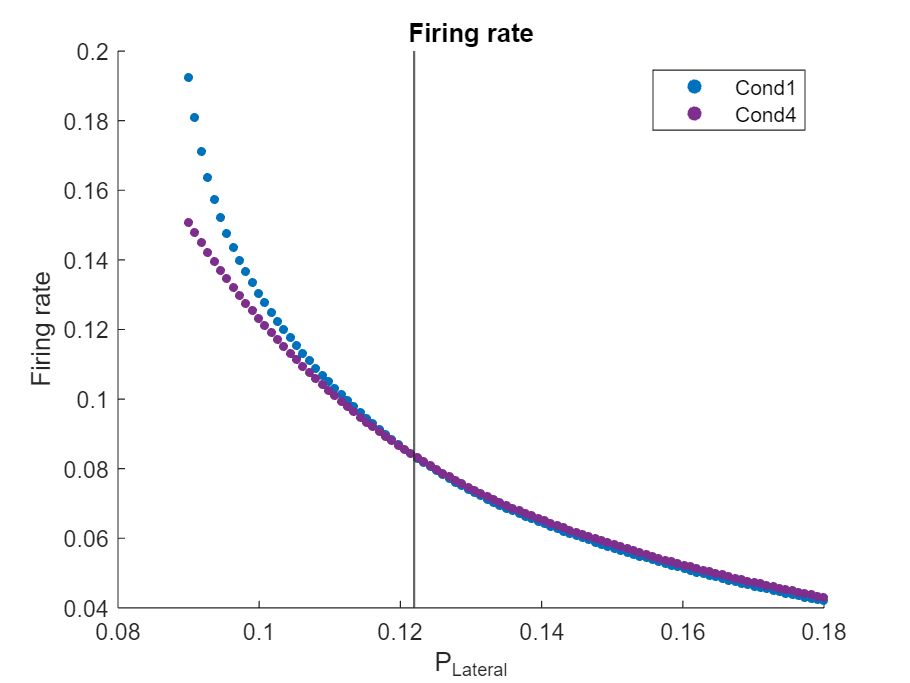

load lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.03_Iattn_0.02.mat
addpath('funcs');

lateral_start = 0.09;
lateral_end = 0.18; 

steps = 100;

sz = 15;
x = linspace(lateral_start,lateral_end,size(PETAsheet,1));
y1 = finalRsheet(:,5,1);
y4 = finalRsheet(:,5,4);

% find zero point
z = y1 - y4; 
[~, idxP] = min(z(z>0));
x0 = (x(idxP) + x(idxP+1))/2;

figure();
s1 = scatter(x,y1,sz,'filled','MarkerFaceColor','#0072BD');
hold on;
s4 = scatter(x,y4,sz,'filled','MarkerFaceColor','#7E2F8E');
xline(x0,'LineWidth',1);

title("Firing rate");
legend([s1 s4],["Cond1","Cond4"]);
xlabel("P_{Lateral}");
ylabel("Firing rate");

## Lateral Pathway

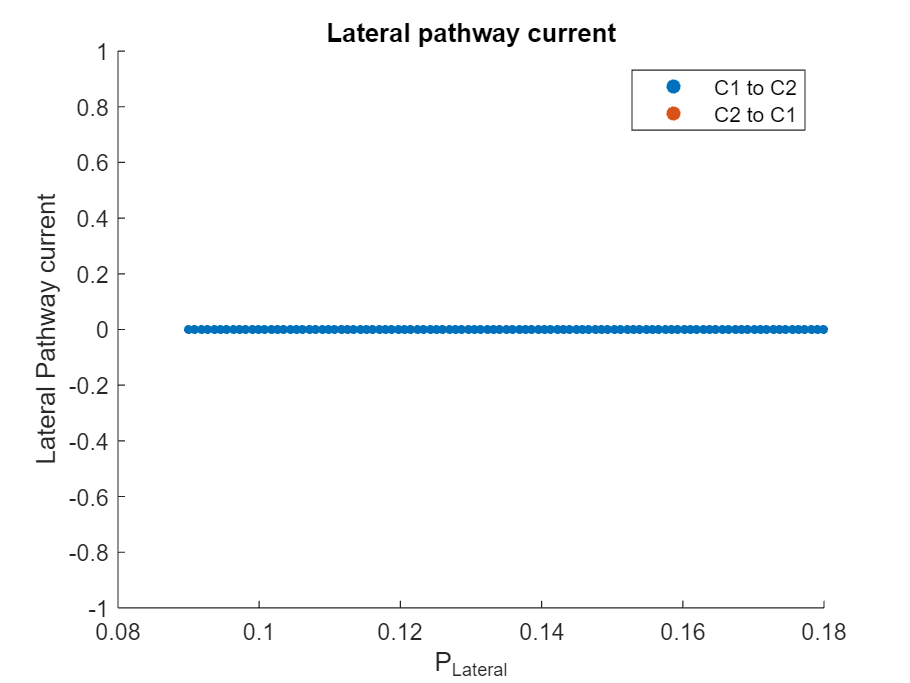

load lateral\finalR_cLateral_0.09_0.18_DeltaE_0.3_DeltaI_0.03_Iattn_0.02.mat
addpath('funcs');

lateral_start = 0.09;
lateral_end = 0.18; 

steps = 100;

sz = 15;
x = linspace(lateral_start,lateral_end,size(PETAsheet,1));
y1 = PETOsheet(:,10,1,4);
y2 = PETOsheet(:,2,9,4);

% find zero point
z = y2-y1; 
[~, idxP] = min(z(z>0));
% x0 = (x(idxP) + x(idxP+1))/2;

figure();
% s1 = scatter(x,y1,sz,'filled','MarkerFaceColor',"#0072BD");
hold on;
s2 = scatter(x,y2,sz,'filled','MarkerFaceColor',"#D95319");
% xline(x0,'LineWidth',1);

title("Lateral pathway current");
legend([s1 s2],["C1 to C2","C2 to C1"]);

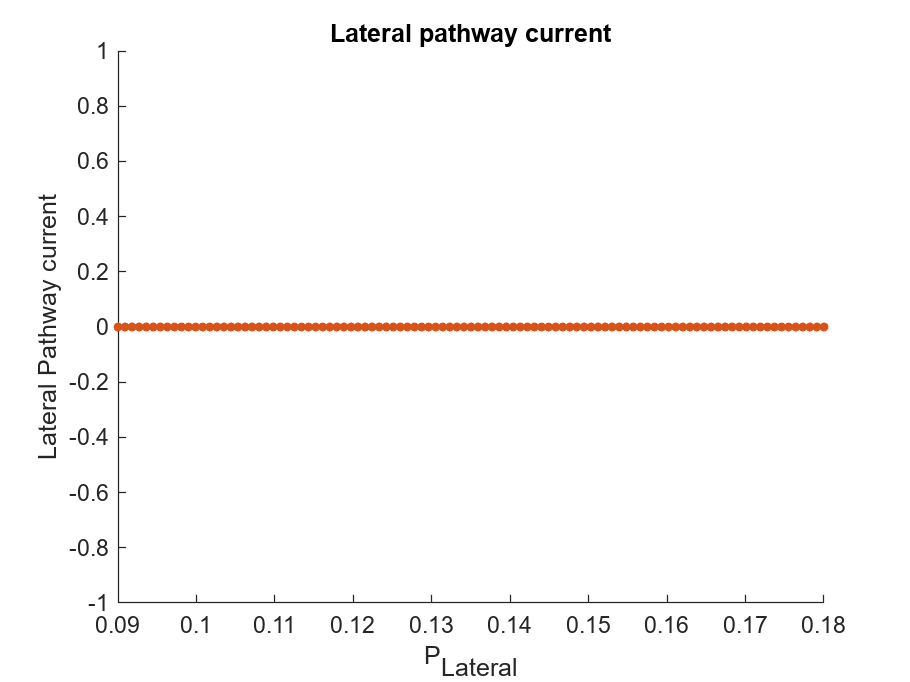

xlabel("P_{Lateral}");
ylabel("Lateral Pathway current");